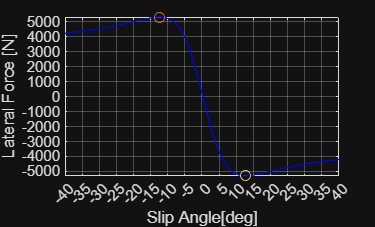

% Lateral Force vs SLip Angle, based on Magic Formula
clear
load("mfparams_2.mat");
CoeffLat = Tire_Coefficients(mfparams, 'c_lat'); 
SFLat = Tire_Scaling_Factors(mfparams, 'sf_lat');


%%settings
%pressure [bar]
pressure = 0.6;
%camber angle
gamma = 0;                            
% Normal force
Fz = 2000;                              
% slip angle
alpha= -40:0.05:40;

%plot
Fy0 = LateralMF(CoeffLat,SFLat,alpha,Fz,gamma,pressure);
plot(alpha,Fy0,'b');

%plot settings
xlabel("Slip Angle[deg]");
xticks(-100:5:100);
%xlim([0 6]);

ylabel("Lateral Force [N]");
yticks(-10000:1000:10000);
         
grid
hold on

% max and min
[FyMax, FyMaxIdx] = max(Fy0);
scatter(alpha(:,FyMaxIdx),FyMax);
alphaMax = alpha(FyMaxIdx);

[FyMin, FyMinIdx] = min(Fy0);
scatter(alpha(:,FyMinIdx),FyMin);
alphaMin = alpha(FyMinIdx);
hold off


X = mean(Fy0./alpha);